## Rover Dimensions

disp('rover width')

rover width


w = .3

w = 0.3000


disp('rover lenght')

rover lenght


l = .4

l = 0.4000

Forcing a maximum of +-40 degrees for the wheels, rotation center will not be nearer then 0.63 meters

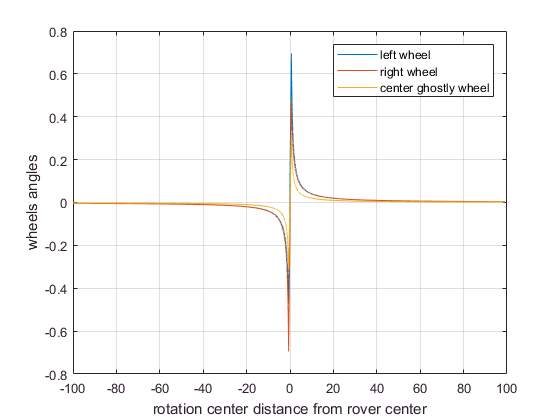

r = [ -100:1:-10.1 -10:.001:-.63 .63:.001:10 10.1:1:100];

left_theta = atan(l./(-w/2+r));
right_theta = atan(l./(+w/2+r));
center_theta = atan(.5*l./(r));

figure()
plot(r,left_theta)
hold on
plot(r,right_theta)
plot(r,center_theta)
legend('left wheel', 'right wheel', 'center ghostly wheel')
xlabel('rotation center distance from rover center')
ylabel('wheels angles')
grid
hold off

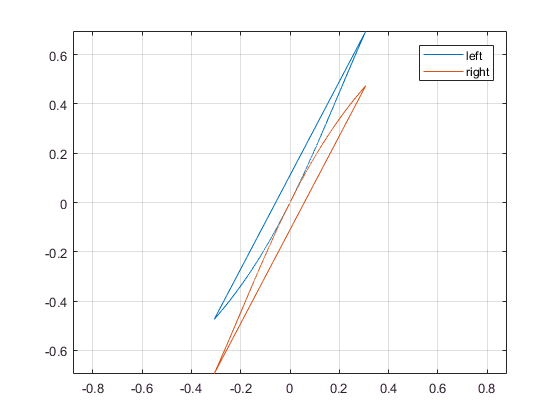


figure()
plot(center_theta, left_theta)
hold on
plot(center_theta, right_theta)
legend('left', 'right')
axis equal
grid
hold off

## Reorganizing left_theta, right_theta and center_theta

If abs(r) < w/2 for any r, this reorganization won't work!

[max_right, index_max_right]=max(right_theta)

max_right = 0.4739

index_max_right = 9462

right_theta = [fliplr(right_theta(1:index_max_right-1)), fliplr(right_theta(index_max_right:end))]

right_theta =    -0.6947   -0.6937   -0.6927   -0.6917   -0.6907   -0.6896   -0.6886   -0.6876   -0.6866   -0.6856   -0.6846   -0.6836   -0.6826   -0.6816   -0.6806   -0.6796   -0.6787   -0.6777   -0.6767   -0.6757   -0.6747   -0.6738   -0.6728   -0.6718   -0.6709   -0.6699   -0.6689   -0.6680   -0.6670   -0.6661   -0.6651   -0.6642   -0.6632   -0.6623   -0.6613   -0.6604   -0.6594   -0.6585   -0.6576   -0.6566   -0.6557   -0.6548   -0.6538   -0.6529   -0.6520   -0.6511   -0.6502   -0.6492   -0.6483   -0.6474


[max_left, index_max_left]=max(left_theta)

max_left = 0.6947

index_max_left = 9462

left_theta = [fliplr(left_theta(1:index_max_left-1)), fliplr(left_theta(index_max_left:end))]

left_theta =    -0.4739   -0.4733   -0.4728   -0.4723   -0.4718   -0.4713   -0.4707   -0.4702   -0.4697   -0.4692   -0.4687   -0.4682   -0.4677   -0.4672   -0.4667   -0.4662   -0.4657   -0.4652   -0.4646   -0.4641   -0.4636   -0.4631   -0.4626   -0.4622   -0.4617   -0.4612   -0.4607   -0.4602   -0.4597   -0.4592   -0.4587   -0.4582   -0.4577   -0.4572   -0.4567   -0.4563   -0.4558   -0.4553   -0.4548   -0.4543   -0.4538   -0.4534   -0.4529   -0.4524   -0.4519   -0.4515   -0.4510   -0.4505   -0.4500   -0.4496


[max_center, index_max_center]=max(center_theta)

max_center = 0.3074

index_max_center = 9462

center_theta = [fliplr(center_theta(1:index_max_center-1)), fliplr(center_theta(index_max_center:end))]

center_theta =    -0.3074   -0.3069   -0.3065   -0.3060   -0.3056   -0.3051   -0.3047   -0.3042   -0.3038   -0.3033   -0.3029   -0.3024   -0.3020   -0.3016   -0.3011   -0.3007   -0.3002   -0.2998   -0.2994   -0.2989   -0.2985   -0.2981   -0.2976   -0.2972   -0.2968   -0.2964   -0.2959   -0.2955   -0.2951   -0.2947   -0.2942   -0.2938   -0.2934   -0.2930   -0.2926   -0.2921   -0.2917   -0.2913   -0.2909   -0.2905   -0.2901   -0.2897   -0.2893   -0.2889   -0.2885   -0.2881   -0.2877   -0.2873   -0.2868   -0.2865


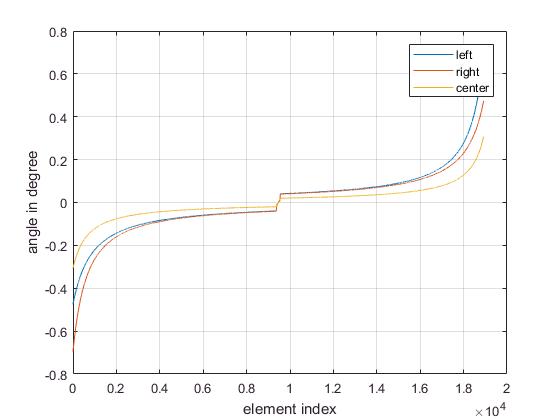


figure()
title('Reorganized left, right and center thetas')
plot(left_theta)
hold on
plot(right_theta)
plot(center_theta)
xlabel('element index')
ylabel('angle in degree')
legend('left', 'right', 'center')
grid
hold off

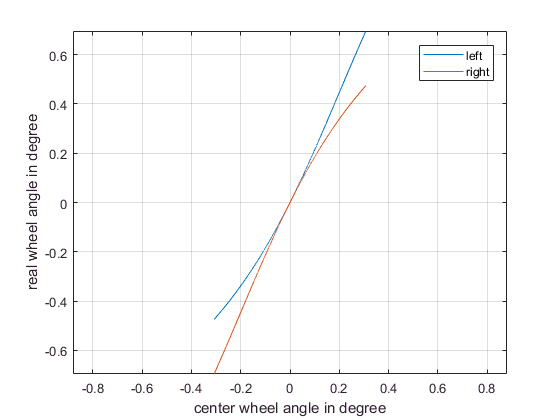


figure()
plot(center_theta*180/pi, left_theta*180/pi)
hold on
plot(center_theta*180/pi, right_theta*180/pi)
xlabel('center wheel angle in degree')
ylabel('real wheel angle in degree')
legend('left', 'right')
axis equal
grid
hold off

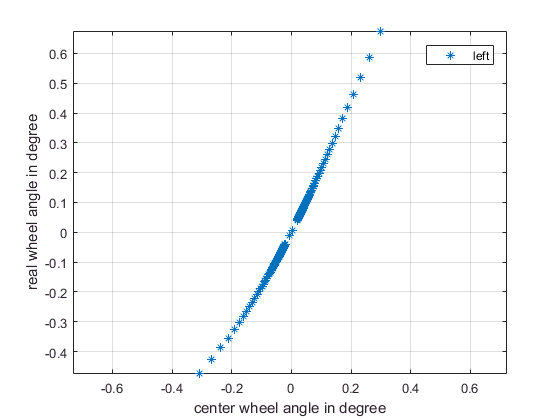

spacing = 100;
figure()
plot(center_theta(1:spacing:end), left_theta(1:spacing:end), '*')
xlabel('center wheel angle in degree')
ylabel('real wheel angle in degree')
legend('left')
axis equal
grid
hold off

## Trying to polyfit stuff here

Indexes to use less points, spaced by approx. 5 degrees

indexes = [1];
for i = 2:length(center_theta)
    if center_theta(i) - center_theta(indexes(end)) > 5*pi/180
        indexes = [indexes i];
    end
end
indexes

indexes =            1         265         868        3759       14761       18011       18642       18914



$$p_1 x^n +p_2 x^{n-1} +\ldotp \ldotp \ldotp +p_n x+p_{n+1}$$



[pleft, ~, mu_left] = polyfit(center_theta(indexes), left_theta(indexes), 5)

pleft =    -0.0005   -0.0067   -0.0090    0.0674    0.4266   -0.0036


mu_left =    -0.0019
    0.2138


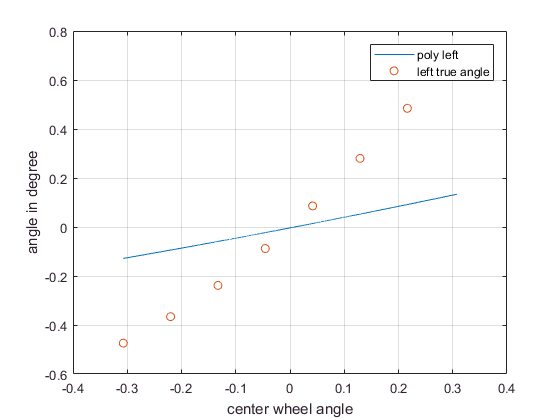


figure()
plot(center_theta, polyval(pleft, center_theta))
hold on
plot(center_theta(indexes), left_theta(indexes), 'o')
xlabel('center wheel angle')
ylabel('angle in degree')
legend('poly left', 'left true angle')
%ylim([-50 50])
grid
hold off

Polyfit is drunk. Forcing right parameters:


pleft=  fliplr([ 9.3610018132620019e-005 2.0041497325730204e+000 1.4716131190668178e+000 -1.0929725380842041e+000 -3.2252012765547819e+000])

pleft =    -3.2252   -1.0930    1.4716    2.0041    0.0001


pright = fliplr([-1.7013070152971507e-004 2.0039379507086514e+000 -1.4684576386267671e+000 -1.0901354124362155e+000 3.1974185558159771e+000])

pright =     3.1974   -1.0901   -1.4685    2.0039   -0.0002


Are these parameters right?

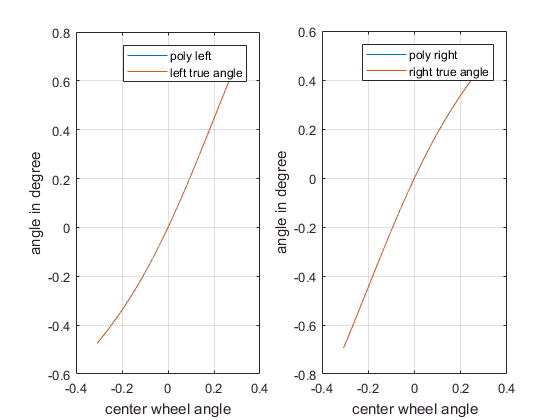

figure()
subplot(1,2,1)
plot(center_theta, polyval(pleft, center_theta))
hold on
plot(center_theta, left_theta)
xlabel('center wheel angle')
ylabel('angle in degree')
legend('poly left', 'left true angle')
%ylim([-50 50])
grid
hold off


subplot(1,2,2)
plot(center_theta, polyval(pright, center_theta))
hold on
plot(center_theta, right_theta)
xlabel('center wheel angle')
ylabel('angle in degree')
legend('poly right', 'right true angle')
%ylim([-50 50])
grid
hold off